# s_watsonPyramid

### **﻿The Field of View, the Field of Resolution, and the Field of Contrast Sensitivity  **

### **Background**

The highest spatial freq that can be detected with a contrast = 1 was used to define the 'Window' of visibility.  This is a contour on the spatio-temporal frequency plane.

This paper extends the Window analysis to describe the sensitivity allowing the contrast to be less than 1.  Accounting for these lower contrasts creates a surface with respect to spatial and temporal frequency. This is  the pyramid (3D) is built on the window (2D).

**Numbers to remember**

When fixated, Beau says the field of view (FOV) of human vision is

-     -65 deg (in) to 105 deg (out)

-     -74 deg (down) to 62 deg (up)

## The Kelly spatial-temporal frequency contrast sensitivity function

In 1979 Don Kelly published a formula defining the space-time contrast sensitivity function.  Suppose we define spatial frequency (cycles per degree) and temporal frequency (hz).  ISETBio has an interface to return the Kelly estimate.  

Beau Watson says use linear spacing for his pyramid.  So we create a set of linear sample values

fs = linspace(1, 30, 80);
ft = linspace(1, 60, 100);

% In this variable, row is space, col is time
contrastSensitivity = humanSpaceTime('kelly79', fs, ft);

%  Visualize the Kelly data using a log(contrastSensitivity).  As Beau
%  points out, the 
surf(ft, fs, contrastSensitivity);
set(gca, 'xscale', 'linear', 'yscale', 'linear','zscale','log');
set(gca, 'xlim', [0 35], 'ylim', [0 20]);
xlabel('Temporal freq (Hz)');
ylabel('Spatial freq (cpd)')
zlabel('Log CS');

I suggest bring the window out of the live script and rotating the surface around. The planar shape, and the low frequency drop, is pretty clear.  You can see the planarity from this point of view.

az = 45; el = 0;
view([az,el]);

## Viewed from the top down, you see the Window of visibility

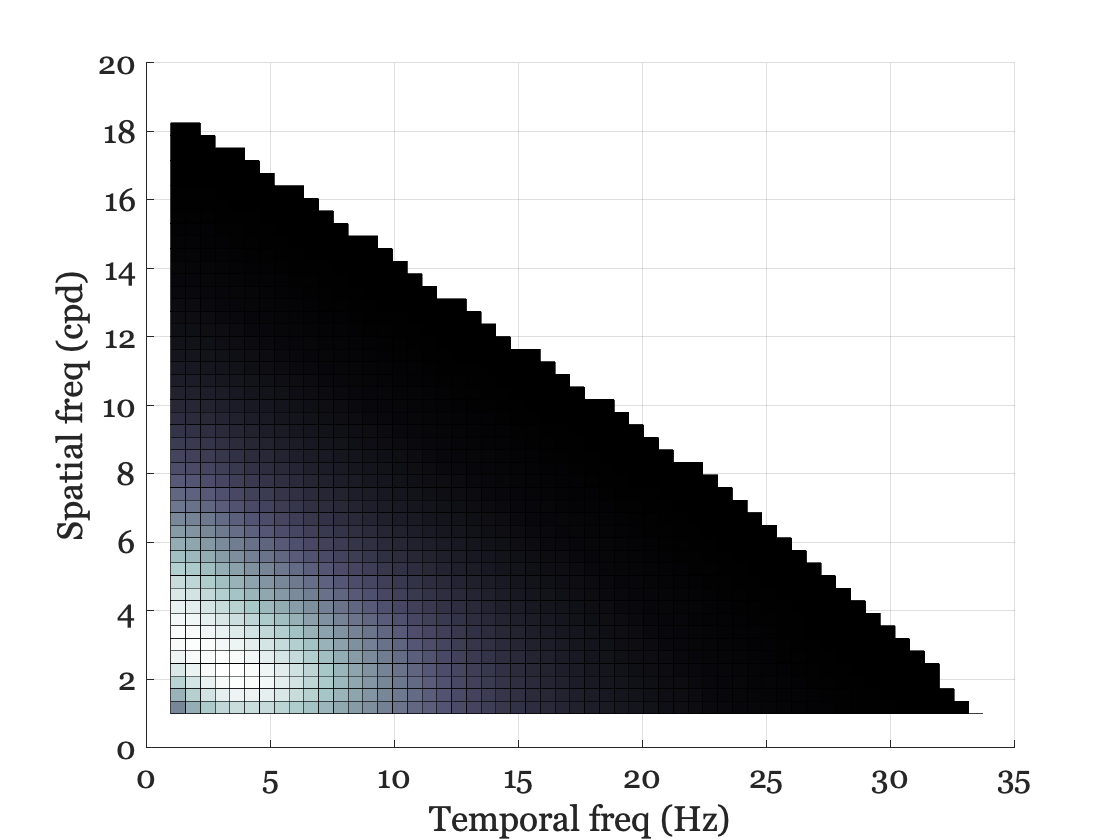

% Spatial and temporal frequencies inside the colored region are visible.
% The white points would require a stimulus you can't really make, with a
% contrast greater than 1.
az = 0; el = 90;
view([az el]);
colormap("bone")

And here we see it as a contour map

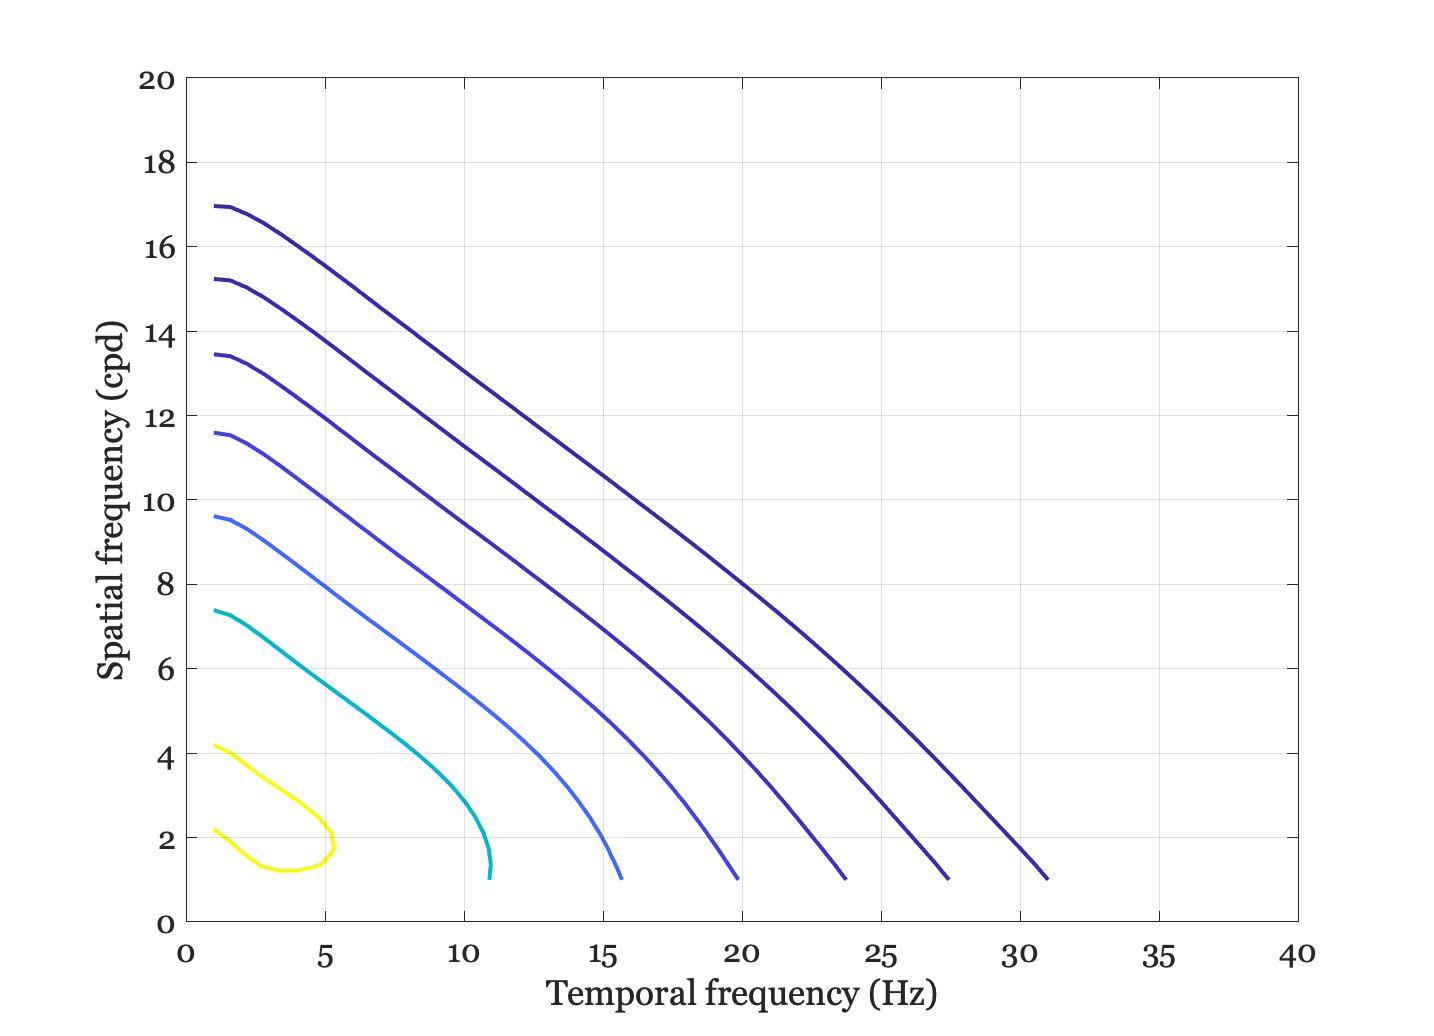

ieNewGraphWin;
contour(ft,fs,contrastSensitivity,logspace(-1,2,10),'LineWidth',2);
grid on
set(gca,'xlim',[0,40],'ylim',[0,20]);
xlabel('Temporal frequency (Hz)');
ylabel('Spatial frequency (cpd)')

## Building the Pyramid

% Beau encourages us to use negative spatial and temporal frequencies.  What does a F and -F sin(2*piF*x) look like?   These stimuli are the same, but with opposite contrast - black is white and white is black.  So using plus and minus F will generate a symmetric plot.

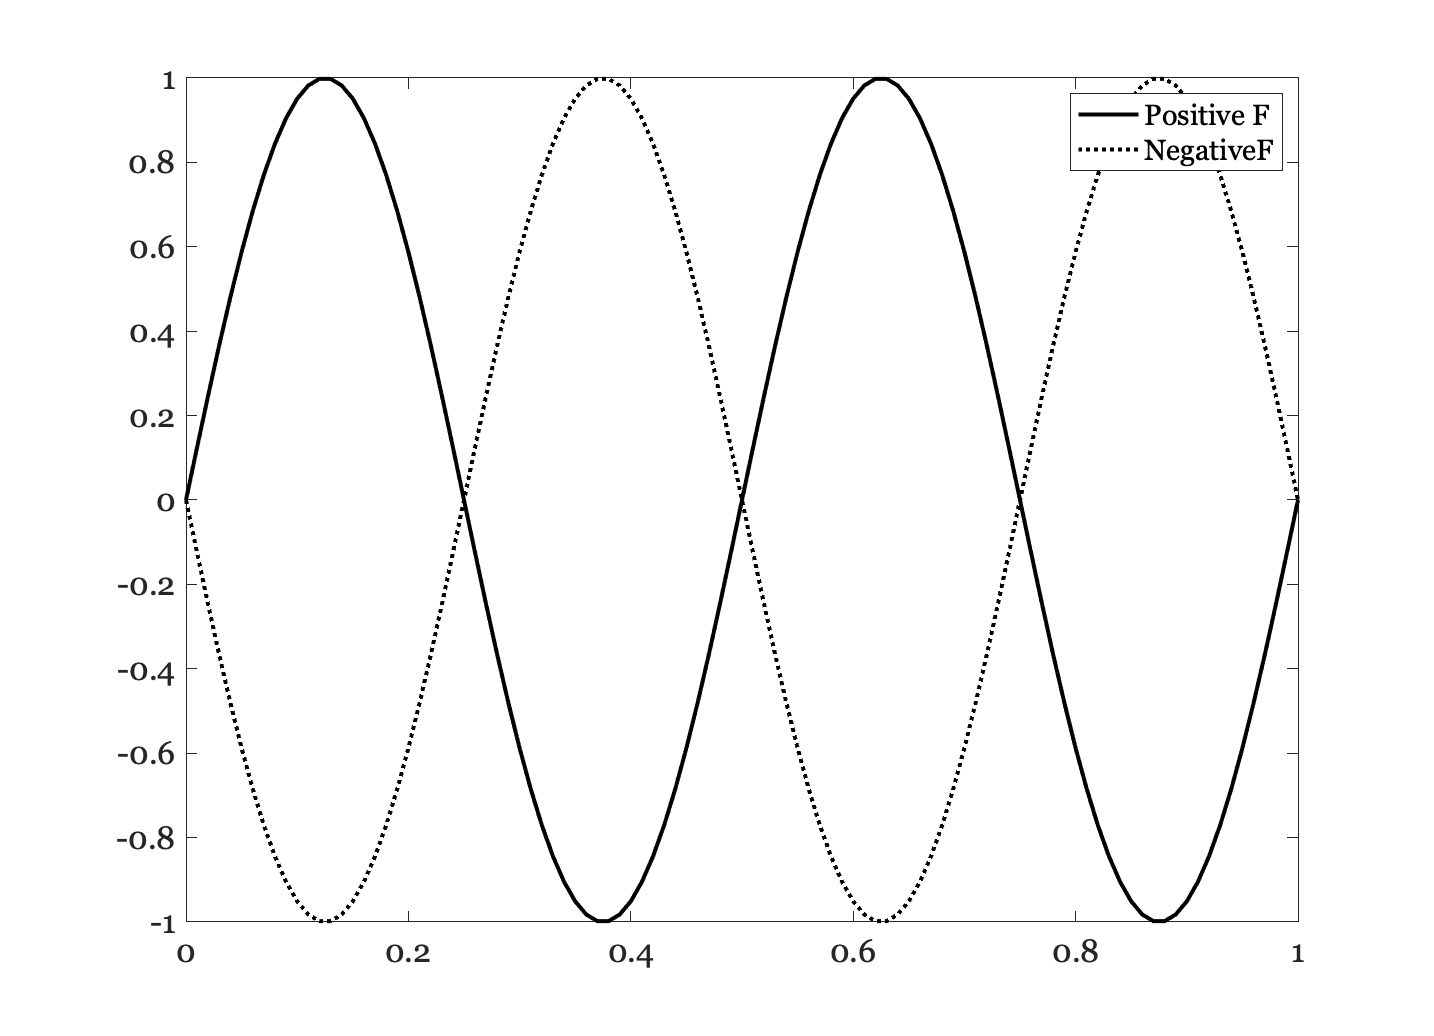

F = 2;
x = (0:0.01:1);
vP = sin(2*pi*F*x);
vN = sin(2*pi*(-1*F)*x);

ieNewGraphWin;
p = plot(x,vP,'k-',x,vN,'k:');
for ii=1:2, p(ii).LineWidth = 2; end
legend({'Positive F','NegativeF '})


% Here we go
Time = [fliplr(-ft),ft];   % The extended temporal frequencies
Space = [fliplr(-fs),fs];  % The extended spatial frequencies


Nothing changes when you measure with positive or negative frequencies, so we can just rotate then paste the same contrast sensitivity function measured with all positive F and W into the other three quadrants, if F  or W are allowed to become negative.  So we just flip the data around to make the full contrast sensitivity variable (CS).

CS = [rot90(contrastSensitivity,2), flipud(contrastSensitivity);
    flipud(rot90(contrastSensitivity,-2)), contrastSensitivity];

## Here is the Pyramid of Visibility.

Here is a look at the new shape. Because there is a little dip in the middle, we might call it the Volcano of Visibility (VoV).

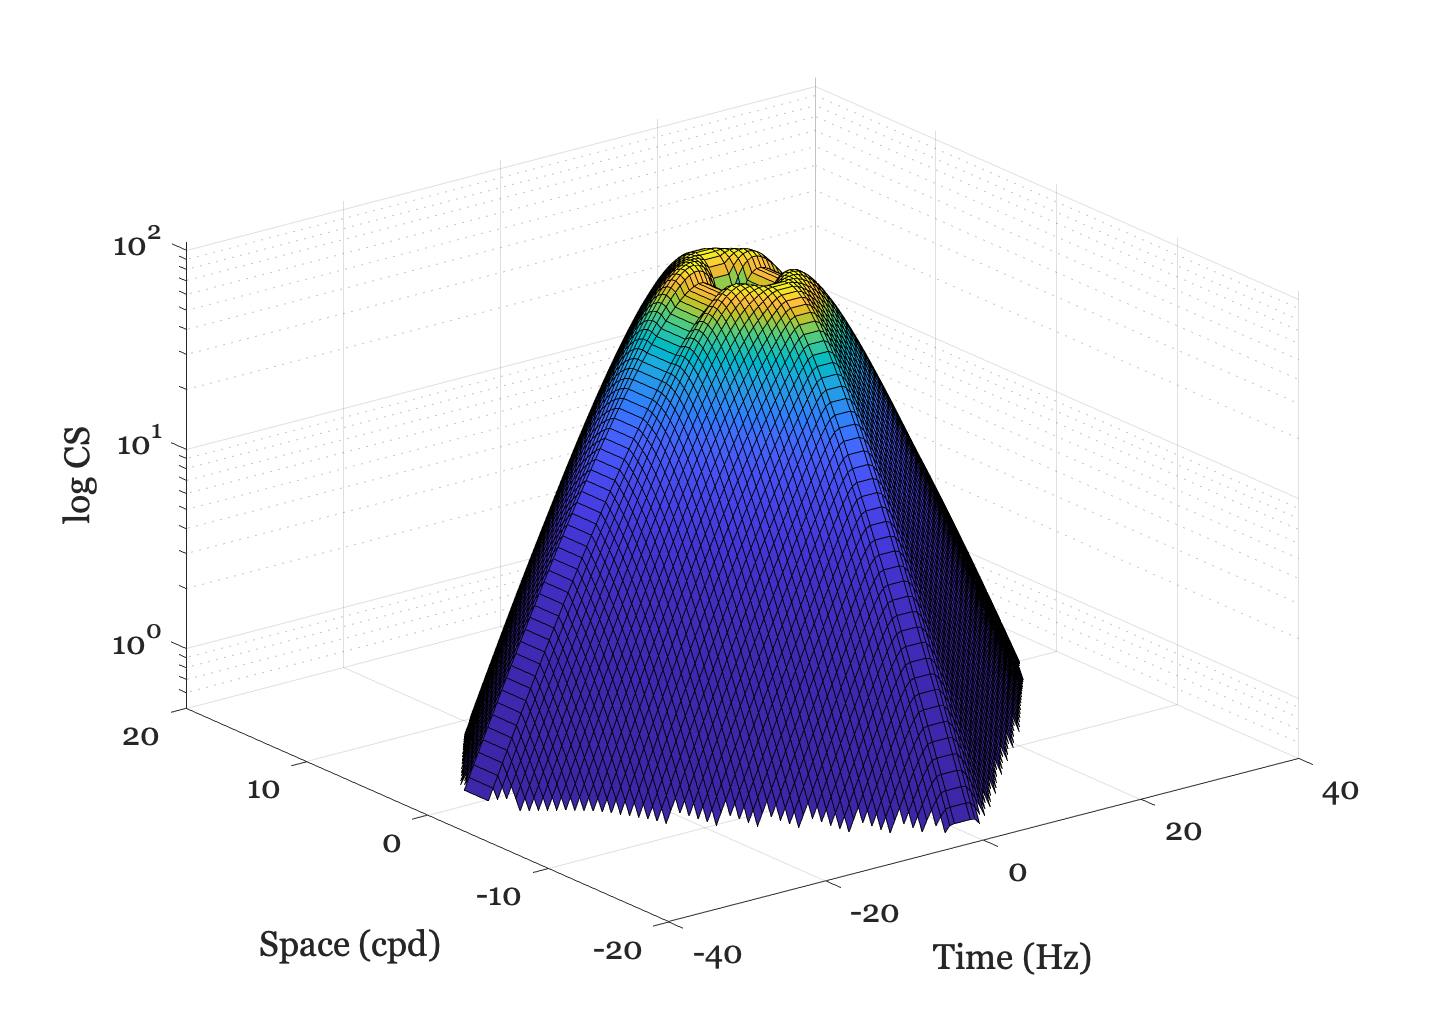

[X,Y] = meshgrid(Time,Space);
surf(X,Y,CS)
ylabel('Space (cpd)');
xlabel('Time (Hz)');
zlabel('log CS')
set(gca, 'xscale', 'linear', 'yscale', 'linear','zscale','log');

## Looking down from the top we see the 'Window of Visibility'

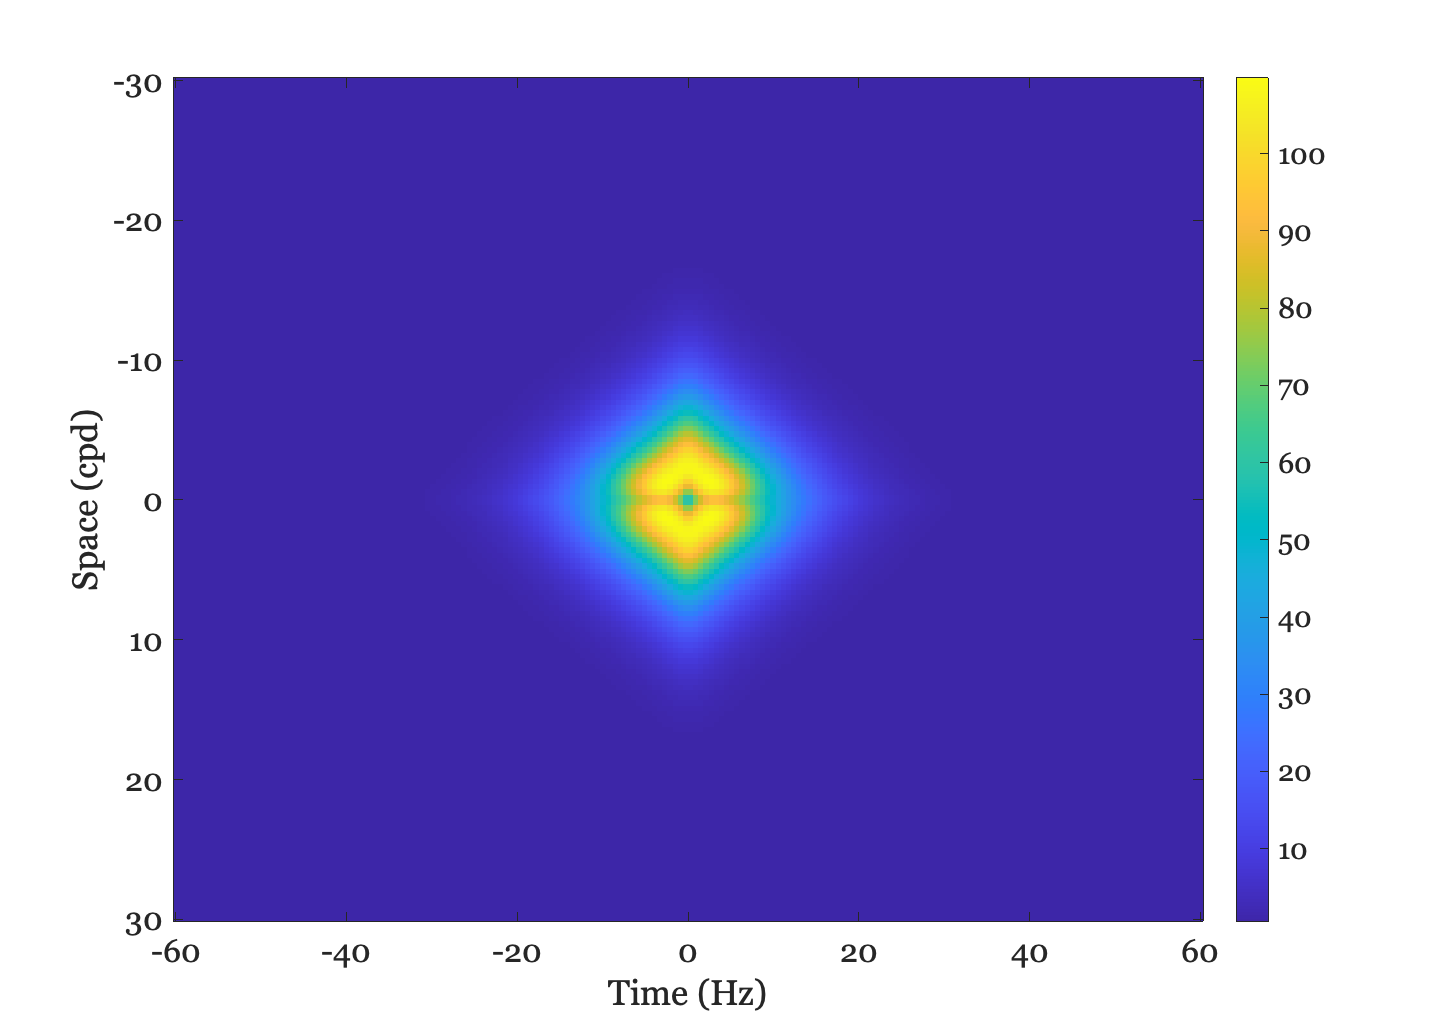

ieNewGraphWin;
imagesc(Time,Space,CS)
ylabel('Space (cpd)');
xlabel('Time (Hz)');
colorbar;

## The changing pyramid as we vary visual field eccentricity

Suppose we are at an eccentricity that scales the effective spatial frequency by a factor of 2.  Then the shape changes like this.

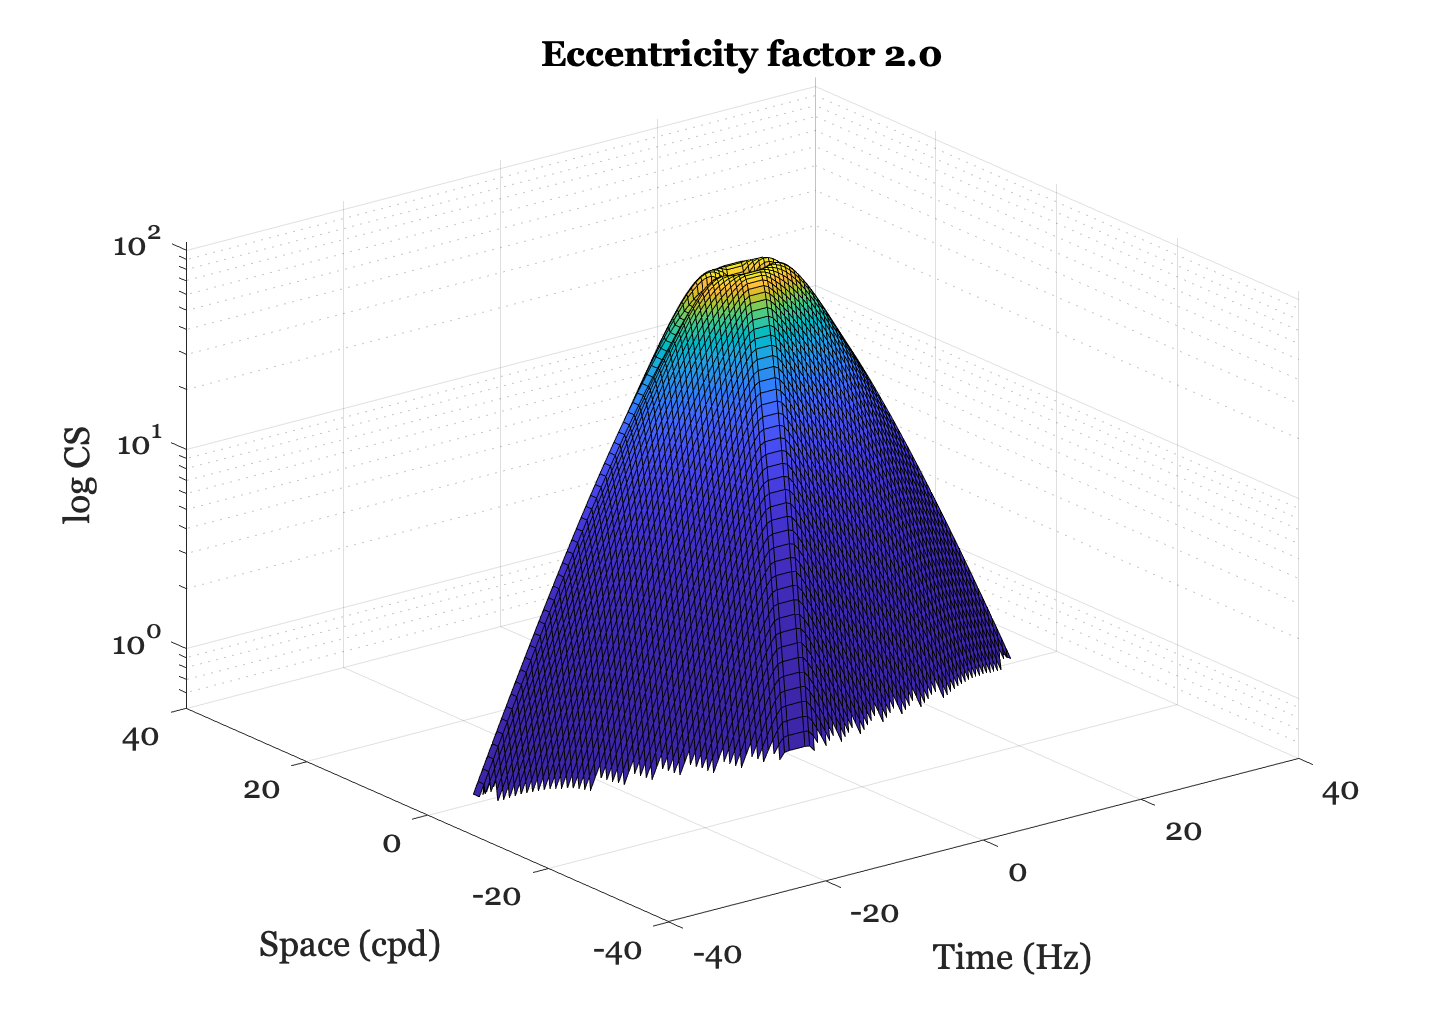

ieNewGraphWin;
eccFactor = 2;
surf(X,Y/eccFactor,CS)
ylabel('Space (cpd)'); xlabel('Time (Hz)'); zlabel('log CS')
set(gca, 'xscale', 'linear', 'yscale', 'linear','zscale','log');
set(gca, 'xlim', [-40 40], 'ylim', [-40 40]);
title(sprintf('Eccentricity factor %.1f',eccFactor));

## END

For applications, we would like to know how the original shape measured by Kelly (and others varies with (a) eccentricity, (b) luminance level, and (c) color.  We would also like an image computable calculation that shows how to use this information.

Beau describes his approach to including eccentricity in Equations (4) and (5). Scale the spatial frequency as if it is a higher spatial frequency than its true physical size, and the scaling factor is given by a linear dependence on eccentricity.

Want to build a Matlab function that takes an image in and produces a sensitivity curve like the Volcano of Visibility for the fovea?  And then for different eccentricities.

## Paper notes need better thinking by me

The first linear equation in the paper is this


$$S = C_0 + C_w W + C_F F + C_L L$$


- S = Log contrast sensitivity

- W - Temporal Freq  (Hz)

- F - Spatial Freq   (cpd)

- L - Luminance (cd/m2)

Beau will give us the constants at some point.

What is the pyramid? Suppose you fix L at 100. Then you have


$$S = (C_0)' + C_w W + C_F F + C_L L$$


This is  OK for the positive quadrant. If we put an absolute value around W and F then values in the other three quadrants would always be the same as the value in the all positive quadrant.

To be a pyramid, notice, we need both positive and negative frequency values. What does that mean exactly? It imposes symmetry in some sense. But the formula for the pyramid doesn't really work with that. If we have +F and -F the S value would be quite different in the linear equation. So, what's up?

## Questions and Notes

We should conditionalize on size and duration of the grating, also mean luminance/color. What is the formula for the CSF in Figure 1? Maybe the formula is in Refs 5-9? Not obvious, though.